# Basics of Translation and Rotation

## Introduction

In this section we will learn how to represent translations and rotations in a 3D space. 

## Translation

Translations are represented by a vector of the same dimensions as the task space $\mathbb{R}^n \rightarrow \mathbb{R}^{n}
$

A translation along x-axis can be represented by $\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack$. 

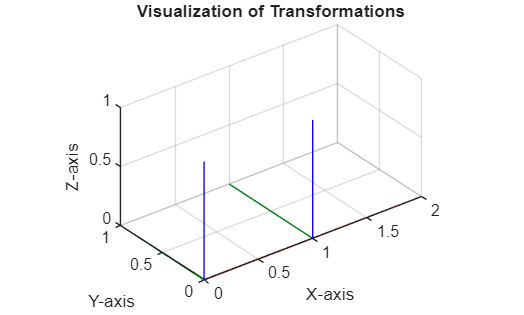

visualizeTranslation([1,0,0]);

For a translation along all axis the vector will be $\left\lbrack \begin{array}{c}
\Delta \;x\\
\Delta \;y\\
\Delta \;z
\end{array}\right\rbrack$. Note that the values are w.r.t. (with respect to) the source frame. 

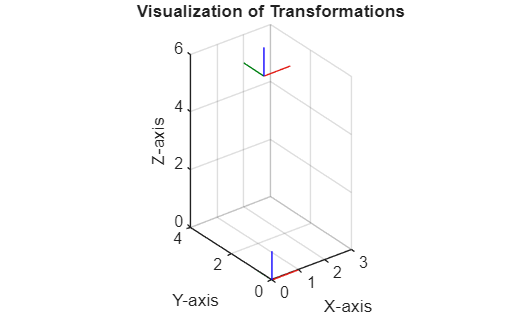

visualizeTranslation([2,3,5]);

### Obtaining the translation vector

We can compute the translation vector by subtracting the coordinate frame origins as: 


$$\mathrm{translation}\;\mathrm{vector}=\mathrm{target}\;\mathrm{frame}-\mathrm{source}\;\mathrm{frame}\;$$


for the example above: 


$$\left\lbrack \begin{array}{c}
t_x \\
t_y \\
t_z 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
3\\
5
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
3\\
5
\end{array}\right\rbrack$$


## Rotations

Rotations can be represented in a few different ways. We are going to work with a matrix representation. Where $R \in  \mathbb{R}^{3x3}
$

The angle of rotation for a  counter clockwise movement  is positive (use right hand rule) 

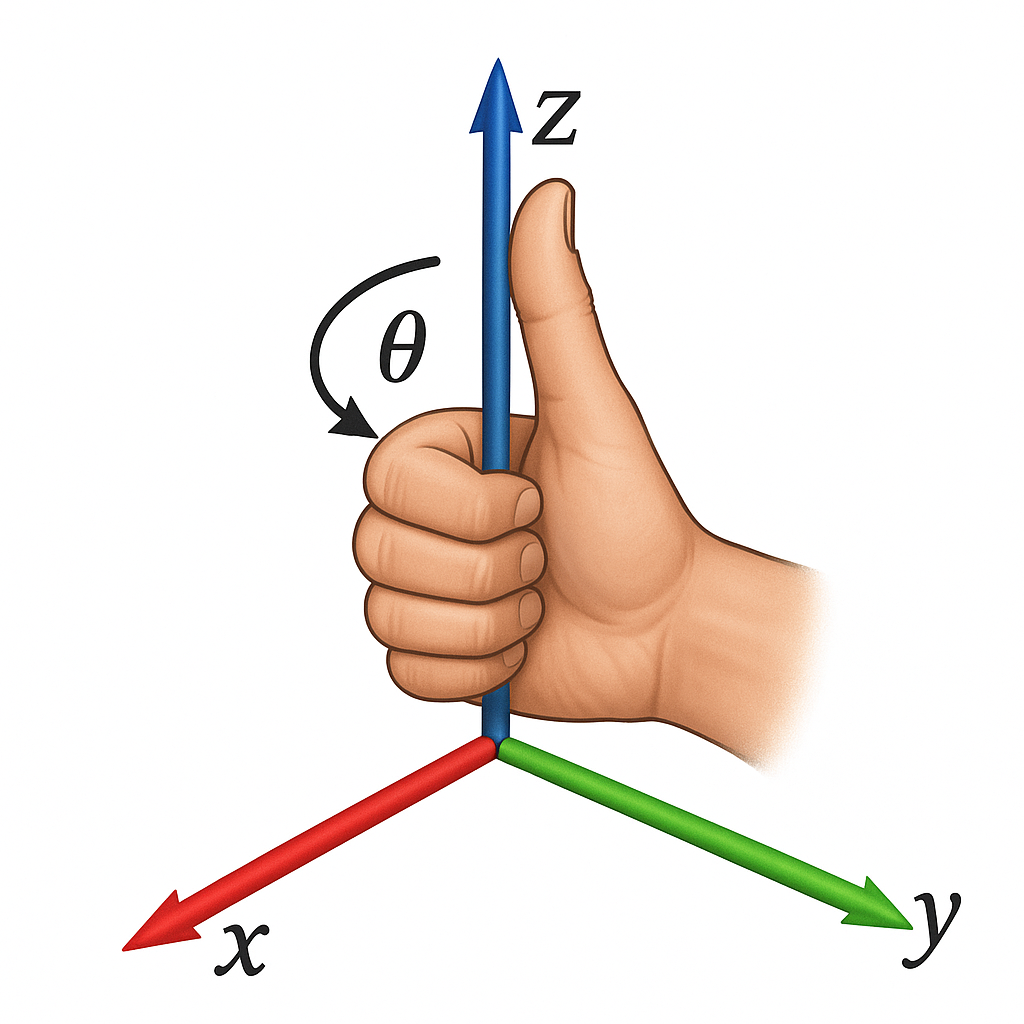

### How to define a simple rotation

We can use prebuild functions to get these matrices for a given rotation. 

syms alpha beta gamma 
Rx=rotx(alpha)

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\mathrm{roll}\right) & -\sin\left(\mathrm{roll}\right)\\ 0 & \sin\left(\mathrm{roll}\right) & \cos\left(\mathrm{roll}\right) \end{array}\right)$$

Ry=roty(beta)

$$Ry = \left(\begin{array}{ccc} \cos\left(\mathrm{pitch}\right) & 0 & \sin\left(\mathrm{pitch}\right)\\ 0 & 1 & 0\\ -\sin\left(\mathrm{pitch}\right) & 0 & \cos\left(\mathrm{pitch}\right) \end{array}\right)$$

Rz=rotz(gamma)

$$Rz = \left(\begin{array}{ccc} \cos\left(\mathrm{yaw}\right) & -\sin\left(\mathrm{yaw}\right) & 0\\ \sin\left(\mathrm{yaw}\right) & \cos\left(\mathrm{yaw}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

Multiplying these rotations with one another, gives us complex rotations in 3D space. 

The order of individual rotations is important for the final matrix, as each consecutive rotation relates to the new coordinate frame. 

clear all; 

### Rotation Notation

In robotics we often need to switch between different ways of describing a 3-D rotation. Instead of giving a full matrix, we can represent any rotation by a set of angles and a specific order. 

The main representations are:

### **Compute Euler Angles (ZYZ)**

Also called **moving-axis** Euler angles (ϕ,  θ,  ψ), as the rotations revolve around the new updated axis:

- Rotate by ϕ about the original z.

- Rotate by θ about the new y.

- Rotate by ψ about the newest z.

syms phi theta psi

$$R = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\psi \right)\,\cos\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right) & -\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)-\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\theta \right)\\ -\cos\left(\psi \right)\,\sin\left(\theta \right) & \sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

R = rotz(phi) * roty(theta) * rotz(psi)

We can also use the build-in functions as:

R = eul2r(phi, theta, psi)

$$R = \left(\begin{array}{ccc} \cos\left(\varphi \right)\,\cos\left(\psi \right)\,\cos\left(\theta \right)-\sin\left(\varphi \right)\,\sin\left(\psi \right) & -\cos\left(\psi \right)\,\sin\left(\varphi \right)-\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sin\left(\psi \right) & \cos\left(\varphi \right)\,\sin\left(\theta \right)\\ \cos\left(\varphi \right)\,\sin\left(\psi \right)+\cos\left(\psi \right)\,\cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\psi \right)-\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sin\left(\psi \right) & \sin\left(\varphi \right)\,\sin\left(\theta \right)\\ -\cos\left(\psi \right)\,\sin\left(\theta \right) & \sin\left(\psi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

#### Compute Euler Angles from Rotation Matrix

For the inverse of this problem (computing the angles from a rotation matrix), we can solve it analytically: 


$$R=\left\lbrack \begin{array}{ccc}
r_{11}  & r_{12}  & r_{13} \\
r_{21}  & r_{22}  & r_{23} \\
r_{31}  & r_{32}  & r_{33} 
\end{array}\right\rbrack$$



$$\phi =\mathrm{atan2}\left(r_{21} ,\;r_{11} \right)=\mathrm{atan2}\left(-r_{21} ,\;-r_{11} \right)$$



$$\theta =\mathrm{atan2}\left(-r_{31} ,\;\sqrt{\;r_{32}^2 +r_{33}^2 }\right)=\mathrm{atan2}\left(-r_{31} ,\;-\sqrt{\;r_{32}^2 +r_{33}^2 }\right)$$



$$\psi =\mathrm{atan2}\left(r_{32} ,\;r_{33} \right)=\mathrm{atan2}\left(-r_{32} ,-r_{33} \right)$$


We can also use the build-in function tr2eul(R). 

For the example values: 


$$\phi = \ 0 \\
\theta = \frac{\pi}{2} \\
\psi = \frac{\pi}{3}
$$


substituting $\phi, \ \theta \ and \ \psi $: 

R_subs = subs(R, [phi, theta, psi], [0, pi/2, pi/3]);  
ZYZ_angles = tr2eul(R_subs)

ZYZ_angles =          0    1.5708    1.0472


clear all; 

### Euler Angles (RPY/ZYX)

Also called **roll-pitch-yaw** (fixed axes) or ZYX Euler angles (roll,  pitch,  yaw). Here the angles correspond to a fixed reference frame where: 

$\theta_r \ = \ Roll \ \ \Rightarrow$ Rotation around X-axis

$\theta_p \ = \ Pitch \ \Rightarrow$ Rotation around Y-axis

$\theta_y \ = \ Yaw \ \ \Rightarrow$ Rotation around Z-axis

This is achieved by applying the angles in the following order:

- Rotate by $\theta_y$ about the original Z.

- Rotate by $\theta_p$ about the original Y.

- Rotate by $\theta_r$ about the original X.

syms roll pitch yaw 
R = rotz(yaw) * roty(pitch) * rotx(roll)

$$R = \left(\begin{array}{ccc} \cos\left(\mathrm{pitch}\right)\,\cos\left(\mathrm{yaw}\right) & \cos\left(\mathrm{yaw}\right)\,\sin\left(\mathrm{pitch}\right)\,\sin\left(\mathrm{roll}\right)-\cos\left(\mathrm{roll}\right)\,\sin\left(\mathrm{yaw}\right) & \sin\left(\mathrm{roll}\right)\,\sin\left(\mathrm{yaw}\right)+\cos\left(\mathrm{roll}\right)\,\cos\left(\mathrm{yaw}\right)\,\sin\left(\mathrm{pitch}\right)\\ \cos\left(\mathrm{pitch}\right)\,\sin\left(\mathrm{yaw}\right) & \cos\left(\mathrm{roll}\right)\,\cos\left(\mathrm{yaw}\right)+\sin\left(\mathrm{pitch}\right)\,\sin\left(\mathrm{roll}\right)\,\sin\left(\mathrm{yaw}\right) & \cos\left(\mathrm{roll}\right)\,\sin\left(\mathrm{pitch}\right)\,\sin\left(\mathrm{yaw}\right)-\cos\left(\mathrm{yaw}\right)\,\sin\left(\mathrm{roll}\right)\\ -\sin\left(\mathrm{pitch}\right) & \cos\left(\mathrm{pitch}\right)\,\sin\left(\mathrm{roll}\right) & \cos\left(\mathrm{pitch}\right)\,\cos\left(\mathrm{roll}\right) \end{array}\right)$$

We can also use the build-in functions as:

R = rpy2r(roll, pitch ,yaw)

$$R = \left(\begin{array}{ccc} \cos\left(\mathrm{pitch}\right)\,\cos\left(\mathrm{yaw}\right) & \cos\left(\mathrm{yaw}\right)\,\sin\left(\mathrm{pitch}\right)\,\sin\left(\mathrm{roll}\right)-\cos\left(\mathrm{roll}\right)\,\sin\left(\mathrm{yaw}\right) & \sin\left(\mathrm{roll}\right)\,\sin\left(\mathrm{yaw}\right)+\cos\left(\mathrm{roll}\right)\,\cos\left(\mathrm{yaw}\right)\,\sin\left(\mathrm{pitch}\right)\\ \cos\left(\mathrm{pitch}\right)\,\sin\left(\mathrm{yaw}\right) & \cos\left(\mathrm{roll}\right)\,\cos\left(\mathrm{yaw}\right)+\sin\left(\mathrm{pitch}\right)\,\sin\left(\mathrm{roll}\right)\,\sin\left(\mathrm{yaw}\right) & \cos\left(\mathrm{roll}\right)\,\sin\left(\mathrm{pitch}\right)\,\sin\left(\mathrm{yaw}\right)-\cos\left(\mathrm{yaw}\right)\,\sin\left(\mathrm{roll}\right)\\ -\sin\left(\mathrm{pitch}\right) & \cos\left(\mathrm{pitch}\right)\,\sin\left(\mathrm{roll}\right) & \cos\left(\mathrm{pitch}\right)\,\cos\left(\mathrm{roll}\right) \end{array}\right)$$

#### Compute RPY Angles from Rotation Matrix

For the inverse of this problem (computing the angles from a rotation matrix), we can solve it analytically: 


$$R=\left\lbrack \begin{array}{ccc}
r_{11}  & r_{12}  & r_{13} \\
r_{21}  & r_{22}  & r_{23} \\
r_{31}  & r_{32}  & r_{33} 
\end{array}\right\rbrack$$



$$\theta_r =\mathrm{atan2}\left(r_{21} ,\;r_{11} \right)=\mathrm{atan2}\left(-r_{21} ,\;-r_{11} \right)$$



$$\theta_p =\mathrm{atan2}\left(-r_{31} ,\;\sqrt{\;r_{32}^2 +r_{33}^2 }\right)=\mathrm{atan2}\left(-r_{31} ,\;-\sqrt{\;r_{32}^2 +r_{33}^2 }\right)$$



$$\theta_y =\mathrm{atan2}\left(r_{32} ,\;r_{33} \right)=\mathrm{atan2}\left(-r_{32} ,-r_{33} \right)$$


We can also use the build-in function tr2rpy(R) 

For the example values: 


$$\theta_r= \ 0 \\
\theta_p= \frac{\pi}{2} \\
\theta_y= \frac{\pi}{3}
$$


substituting $\phi, \ \theta \ and \ \psi $: 

R_subs = subs(R, [roll, pitch, yaw], [0, pi/2, pi/3]); 
RPY_angles = tr2rpy(R_subs)

RPY_angles =          0    1.5708    1.0472


clear all; 

### Quaternions

Quaternions provide a four-parameter, singularity-free way to encode any 3D rotation.

A unit quaternion is represented by $q=\left\lbrack w\;,x,y,z\right\rbrack$

The Rotation matrix can be constructed as: 


$$R=\left\lbrack \begin{array}{ccc}
2\cdot \;\left(w^2 +x^2 \right)-1 & 2\cdot \;\left(x\cdot \;y-w\cdot z\right) & 2\cdot \;\left(x\cdot z-w\cdot y\right)\\
2\cdot \;\left(x\cdot \;y-w\cdot z\right) & 2\cdot \;\left(w^2 +y^2 \right)-1 & 2\cdot \;\left(y\cdot z-w\cdot x\right)\\
2\cdot \;\left(x\cdot z-w\cdot y\right) & 2\cdot \;\left(y\cdot z-w\cdot x\right) & 2\cdot \;\left(w^2 +z^2 \right)-1
\end{array}\right\rbrack$$


We can use build-in functions to compute the Rotation Matrix from Quaternions: 

q = [0.3	0.9	0	0.3];
R=quat2rotm(q)

R =     0.8182   -0.1818    0.5455
    0.1818   -0.8182   -0.5455
    0.5455    0.5455   -0.6364


#### Compute RPY Angles from Rotation Matrix

q=rotm2quat(R)

q =     0.3015    0.9045         0    0.3015
